%% COMPARATIVA BASE VS CONTROLADOR 1 VS CONTROLADOR 2
% Casos:
% - Base 16 m/s constante
% - Base 16 m/s turbulento
% - Controlador 1 constante
% - Controlador 1 turbulento
% - Controlador 2 constante
% - Controlador 2 turbulento

clear; close all; clc;

%% Rutas

rootDir    = fullfile(getenv('USERPROFILE'), 'Desktop', 'TFM_OpenFast');
toolboxDir = fullfile(rootDir, 'Matlab', 'Matlab_Toolbox');
resRoot    = fullfile(rootDir, 'Resultados');

addpath(genpath(toolboxDir));

outDir = fullfile(resRoot, 'Comparativa_Base_C1_C2');

if ~exist(outDir, 'dir')
    mkdir(outDir);
end

figDir = fullfile(outDir, 'Figuras');

if ~exist(figDir, 'dir')
    mkdir(figDir);
end

disp("Comprobando ReadFASTbinary:");

Comprobando ReadFASTbinary:


which ReadFASTbinary

C:\Users\DAVID\Desktop\TFM_OpenFast\Matlab\Matlab_Toolbox\matlab-toolbox-main\Utilities\ReadFASTbinary.m



%% Parámetros generales

tTrans = 500;        % transitorio descartado
mDEL = 10;           % exponente de fatiga
Neq = 1e6;           % ciclos equivalentes
betaRateMax = 2;     % deg/s

%% Definición de casos

cases = struct([]);

% BASE CONSTANTE
cases(1).id = "Base_CasoA_v16_constante";
cases(1).grupo = "Constante";
cases(1).tipo = "Base";
cases(1).label = "Base - 16 m/s constante";
cases(1).dir = fullfile(resRoot, 'CasoA_v16_constante');

% BASE TURBULENTO
cases(2).id = "Base_CasoB_v16_turbulento";
cases(2).grupo = "Turbulento";
cases(2).tipo = "Base";
cases(2).label = "Base - 16 m/s turbulento";
cases(2).dir = fullfile(resRoot, 'CasoB_v16_turbulento');

% CONTROLADOR 1 CONSTANTE
cases(3).id = "C1_CasoA_v16_constante";
cases(3).grupo = "Constante";
cases(3).tipo = "Controlador1";
cases(3).label = "Controlador 1 - 16 m/s constante";
cases(3).dir = fullfile(resRoot, 'Controlador1_v4_KI3e7_Sat05_CasoA_v16_constante');

% CONTROLADOR 1 TURBULENTO
cases(4).id = "C1_CasoB_v16_turbulento";
cases(4).grupo = "Turbulento";
cases(4).tipo = "Controlador1";
cases(4).label = "Controlador 1 - 16 m/s turbulento";
cases(4).dir = fullfile(resRoot, 'Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento');

% CONTROLADOR 2 CONSTANTE
cases(5).id = "C2_CasoA_v16_constante";
cases(5).grupo = "Constante";
cases(5).tipo = "Controlador2";
cases(5).label = "Controlador 2 PI KP=-1e-6 - 16 m/s constante";
cases(5).dir = fullfile(resRoot, 'Controlador2_v4_KPneg1e-6_KI3e-7_CasoA_v16_constante');

% CONTROLADOR 2 TURBULENTO
cases(6).id = "C2_CasoB_v16_turbulento";
cases(6).grupo = "Turbulento";
cases(6).tipo = "Controlador2";
cases(6).label = "Controlador 2 PI KP=-1e-6 - 16 m/s turbulento";
cases(6).dir = fullfile(resRoot, 'Controlador2_v4_KPneg1e-6_KI3e-7_CasoB_v16_turbulento');

%% Leer archivos .outb

for k = 1:numel(cases)

    outbFile = fullfile(cases(k).dir, 'IEA-15-240-RWT-UMaineSemi.outb');

    fprintf("\nLeyendo: %s\n", cases(k).label);

    if ~isfile(outbFile)
        error("No se encuentra el archivo: %s", outbFile);
    end

    [X, ChanName, ChanUnit] = ReadFASTbinary(outbFile);

    cases(k).X = X;
    cases(k).names = cleanNames(ChanName);
    cases(k).units = cleanNames(ChanUnit);
    cases(k).t = getChan(cases(k), "Time");
    cases(k).idx = cases(k).t >= tTrans;
    cases(k).S = buildSignals(cases(k));

    fprintf("Muestras: %d | Canales: %d | Tiempo final: %.1f s\n", ...
        size(X,1), size(X,2), max(cases(k).t));
end


Leyendo: Base - 16 m/s constante


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 18:11:56 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


Muestras: 80001 | Canales: 924 | Tiempo final: 2000.0 s



Leyendo: Base - 16 m/s turbulento


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 11-Aug-2026 at 19:18:39 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


Muestras: 80001 | Canales: 924 | Tiempo final: 2000.0 s



Leyendo: Controlador 1 - 16 m/s constante


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador1_v4_KI3e7_Sat05_CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 15-Aug-2026 at 22:47:52 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


Muestras: 80001 | Canales: 924 | Tiempo final: 2000.0 s



Leyendo: Controlador 1 - 16 m/s turbulento


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador1_v4_KI3e7_Sat05_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 15-Aug-2026 at 23:02:58 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


Muestras: 80001 | Canales: 924 | Tiempo final: 2000.0 s



Leyendo: Controlador 2 PI KP=-1e-6 - 16 m/s constante


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador2_v4_KPneg1e-6_KI3e-7_CasoA_v16_constante\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 16-Aug-2026 at 19:23:58 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


Muestras: 80001 | Canales: 924 | Tiempo final: 2000.0 s



Leyendo: Controlador 2 PI KP=-1e-6 - 16 m/s turbulento


Reading from the file C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Controlador2_v4_KPneg1e-6_KI3e-7_CasoB_v16_turbulento\IEA-15-240-RWT-UMaineSemi.outb with heading: 
   "Predictions were generated on 17-Aug-2026 at 18:29:04 using OpenFAST, compiled on Aug 06 2025 at 19:22:48 as a 64-bit application using single precision at commit v4.1.2 linked with  NWTC Subroutine Library; ElastoDyn; InflowWind; AeroDyn; ServoDyn; SeaState; HydroDyn; MoorDyn (v2.3.8, 2025-02-27); Description from the FAST input file: IEA 15 MW offshore reference model on UMaine VolturnUS-S semi-submersible floating platform".


Muestras: 80001 | Canales: 924 | Tiempo final: 2000.0 s



%% Cálculo de métricas principales

summaryRows = {};

for k = 1:numel(cases)

    C = cases(k);
    S = C.S;
    idx = C.idx;
    tUseful = C.t(idx);

    % DEL medio en raíz de pala, MN·m
    del1 = calcDEL(S.RootMyb1(idx)/1000, mDEL, Neq);
    del2 = calcDEL(S.RootMyb2(idx)/1000, mDEL, Neq);
    del3 = calcDEL(S.RootMyb3(idx)/1000, mDEL, Neq);
    DEL_mean = mean([del1 del2 del3], 'omitnan');

    % NAT pitch total
    nat1 = calcNAT(tUseful, S.BldPitch1(idx), betaRateMax);
    nat2 = calcNAT(tUseful, S.BldPitch2(idx), betaRateMax);
    nat3 = calcNAT(tUseful, S.BldPitch3(idx), betaRateMax);
    NAT_mean_pct = 100 * mean([nat1 nat2 nat3], 'omitnan');

    % Métricas de operación
    STD_Pg = std(S.GenPwr_MW(idx), 'omitnan');
    STD_RotSpeed = std(S.RotSpeed(idx), 'omitnan');

    RMS_PtfmPitch = rmsDemean(S.PtfmPitch(idx));
    RMS_PtfmSurge = rmsDemean(S.PtfmSurge(idx));

    RMS_Mtilt = rmsDemean(S.Mtilt(idx));
    RMS_Myaw  = rmsDemean(S.Myaw(idx));

    Mean_Power = mean(S.GenPwr_MW(idx), 'omitnan');
    Mean_RotSpeed = mean(S.RotSpeed(idx), 'omitnan');
    Mean_Pitch = mean([S.BldPitch1(idx); S.BldPitch2(idx); S.BldPitch3(idx)], 'omitnan');

    summaryRows(end+1,:) = {
        char(C.grupo), ...
        char(C.tipo), ...
        char(C.label), ...
        DEL_mean, ...
        NAT_mean_pct, ...
        STD_Pg, ...
        STD_RotSpeed, ...
        RMS_PtfmPitch, ...
        RMS_PtfmSurge, ...
        RMS_Mtilt, ...
        RMS_Myaw, ...
        Mean_Power, ...
        Mean_RotSpeed, ...
        Mean_Pitch
    };
end

resumenComparativa = cell2table(summaryRows, ...
    'VariableNames', {'Grupo','Tipo','Caso', ...
    'DEL_RootMyb_mean_MNm','NAT_pitch_mean_pct', ...
    'STD_Pg_MW','STD_RotSpeed_rpm', ...
    'RMS_PtfmPitch_deg','RMS_PtfmSurge_m', ...
    'RMS_Mtilt_kNm','RMS_Myaw_kNm', ...
    'Mean_Power_MW','Mean_RotSpeed_rpm','Mean_Pitch_deg'});

disp("Resumen general Base vs C1 vs C2:");

Resumen general Base vs C1 vs C2:


disp(resumenComparativa);

        Grupo               Tipo                                Caso                           DEL_RootMyb_mean_MNm    NAT_pitch_mean_pct    STD_Pg_MW    STD_RotSpeed_rpm    RMS_PtfmPitch_deg    RMS_PtfmSurge_m    RMS_Mtilt_kNm    RMS_Myaw_kNm    Mean_Power_MW    Mean_RotSpeed_rpm    Mean_Pitch_deg
    ______________    ________________    _________________________________________________    ____________________    __________________    _________    ________________    _________________    _______________    _____________    ____________    _____________


writetable(resumenComparativa, fullfile(outDir, 'resumen_base_C1_C2.csv'));

%% Diagnóstico de pitch individual IPC real

ipcRows = {};

for k = 1:numel(cases)

    C = cases(k);
    S = C.S;
    idx = C.idx;
    t = C.t(idx);

    B = [S.BldPitch1(idx), S.BldPitch2(idx), S.BldPitch3(idx)];

    betaMean = mean(B, 2, 'omitnan');
    betaIPC = B - betaMean;

    rmsIPC = sqrt(mean(betaIPC.^2, 1, 'omitnan'));
    maxIPC = max(abs(betaIPC), [], 1);

    betaDotIPC = zeros(size(betaIPC));

    for j = 1:3
        betaDotIPC(2:end,j) = diff(betaIPC(:,j)) ./ diff(t);
    end

    NAT_IPC_pct = 100 * mean(abs(betaDotIPC), 1, 'omitnan') / betaRateMax;

    ipcRows(end+1,:) = {
        char(C.grupo), ...
        char(C.tipo), ...
        char(C.label), ...
        mean(rmsIPC), ...
        max(maxIPC), ...
        mean(NAT_IPC_pct)
    };
end

ipcDiagnostic = cell2table(ipcRows, ...
    'VariableNames', {'Grupo','Tipo','Caso', ...
    'RMS_IPC_pitch_deg','Max_IPC_pitch_deg','NAT_IPC_pitch_pct'});

disp("Diagnóstico de pitch individual IPC:");

Diagnóstico de pitch individual IPC:


disp(ipcDiagnostic);

        Grupo               Tipo                                Caso                           RMS_IPC_pitch_deg    Max_IPC_pitch_deg    NAT_IPC_pitch_pct
    ______________    ________________    _________________________________________________    _________________    _________________    _________________

    {'Constante' }    {'Base'        }    {'Base - 16 m/s constante'                      }       8.6605e-16           1.7764e-15           1.1269e-12    
    {'Turbulento'}    {'Base'        }    {'Base - 16 m/s turbulento'                     }        8.172e-16           1.7764e-15            9.257e-13    
    {'Constante' }    {'Controlador1'}    {'Controlador 1 - 16 m/s constante'             }          0.48591              0.70727               21.652    
    {'Turbulento'}  


writetable(ipcDiagnostic, fullfile(outDir, 'diagnostico_pitch_IPC_base_C1_C2.csv'));

%% Comparativa porcentual frente a Base por grupo

metricNames = resumenComparativa.Properties.VariableNames(4:end);

pctRows = {};

grupos = ["Constante", "Turbulento"];
controladores = ["Controlador1", "Controlador2"];

for g = grupos

    idxBase = strcmp(resumenComparativa.Grupo, char(g)) & strcmp(resumenComparativa.Tipo, "Base");

    for c = controladores

        idxCtrl = strcmp(resumenComparativa.Grupo, char(g)) & strcmp(resumenComparativa.Tipo, char(c));

        if ~any(idxCtrl)
            continue;
        end

        for m = 1:numel(metricNames)

            metric = metricNames{m};

            baseVal = resumenComparativa{idxBase, metric};
            ctrlVal = resumenComparativa{idxCtrl, metric};

            pctChange = 100 * (ctrlVal - baseVal) / baseVal;

            pctRows(end+1,:) = {
                char(g), ...
                char(c), ...
                metric, ...
                baseVal, ...
                ctrlVal, ...
                pctChange
            };
        end
    end
end

comparativaPct = cell2table(pctRows, ...
    'VariableNames', {'Grupo','Controlador','Metrica','Base','ValorControlador','Cambio_pct'});

disp("Cambio porcentual frente a Base:");

Cambio porcentual frente a Base:


disp(comparativaPct);

        Grupo           Controlador               Metrica               Base      ValorControlador    Cambio_pct
    ______________    ________________    ________________________    ________    ________________    __________

    {'Constante' }    {'Controlador1'}    {'DEL_RootMyb_mean_MNm'}      7.0268          5.3674           -23.615
    {'Constante' }    {'Controlador1'}    {'NAT_pitch_mean_pct'  }      0.4494          21.936            4781.2
    {'Constante' }    {'Controlador1'}    {'STD_Pg_MW'           }    0.045391        0.046999             3.544
    {'Constante' }    {'Controlador1'}    {'STD_RotSpeed_rpm'    }    0.022877        0.023688             3.544
    {'Constante' }    {'Controlador1'}    {'RMS_PtfmPitch_deg'   }    0.057198        0.058432            2.1584
    

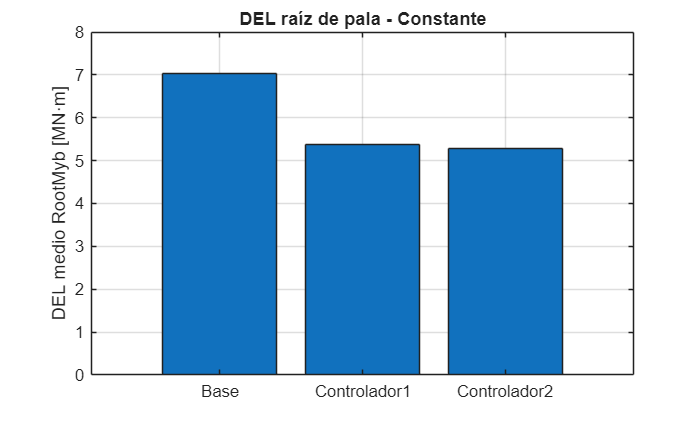

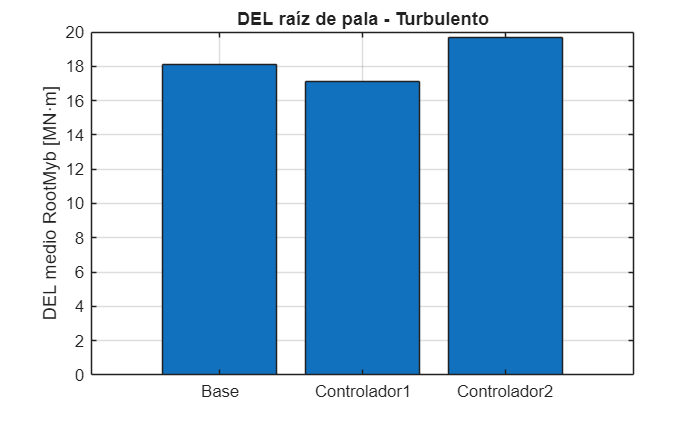


writetable(comparativaPct, fullfile(outDir, 'cambio_porcentual_base_C1_C2.csv'));

%% Figuras principales: barras DEL

for g = grupos

    idxG = strcmp(resumenComparativa.Grupo, char(g));

    figure;
    bar(categorical(resumenComparativa.Tipo(idxG)), resumenComparativa.DEL_RootMyb_mean_MNm(idxG));
    grid on;
    ylabel('DEL medio RootMyb [MN·m]');
    title("DEL raíz de pala - " + g);

    saveas(gcf, fullfile(figDir, sprintf('DEL_Base_C1_C2_%s.png', char(g))));
end

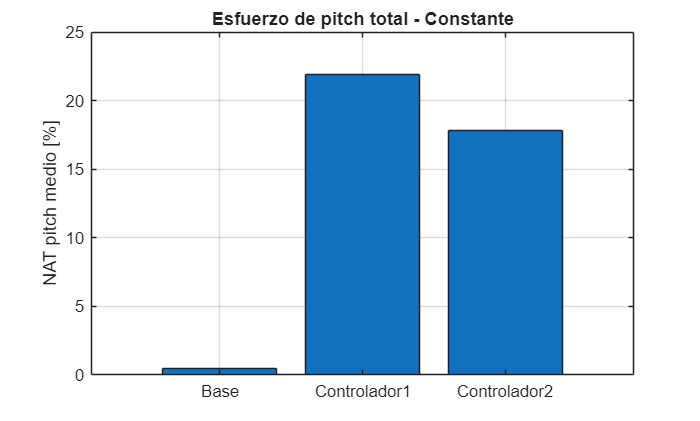

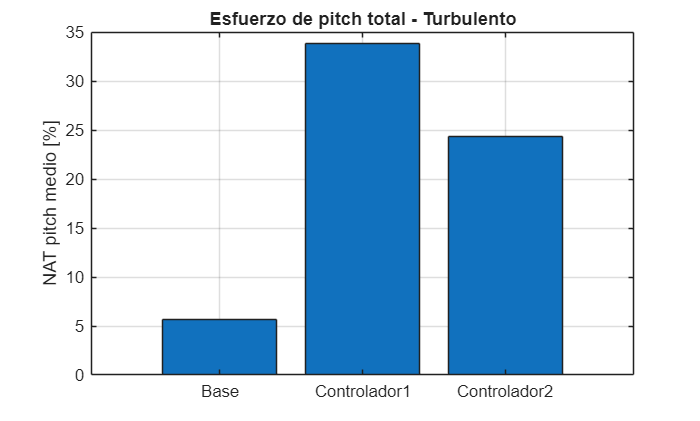


%% Figuras principales: barras NAT total

for g = grupos

    idxG = strcmp(resumenComparativa.Grupo, char(g));

    figure;
    bar(categorical(resumenComparativa.Tipo(idxG)), resumenComparativa.NAT_pitch_mean_pct(idxG));
    grid on;
    ylabel('NAT pitch medio [%]');
    title("Esfuerzo de pitch total - " + g);

    saveas(gcf, fullfile(figDir, sprintf('NAT_Total_Base_C1_C2_%s.png', char(g))));
end

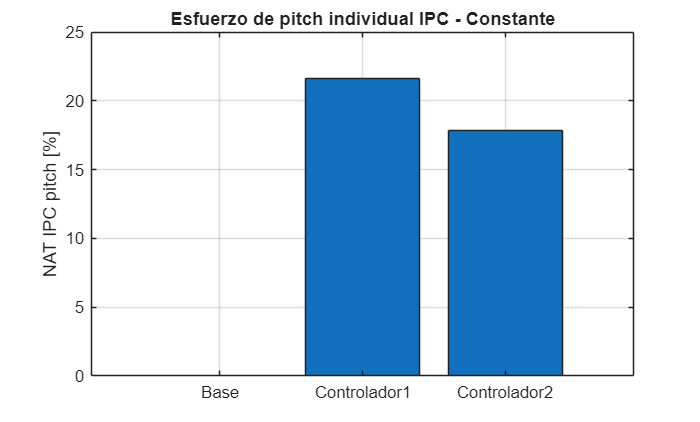

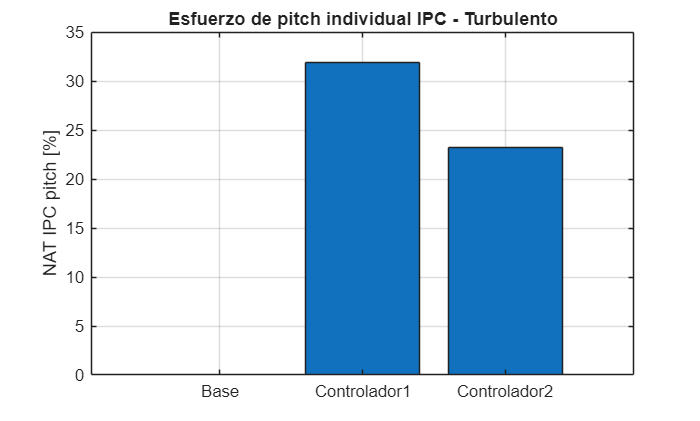


%% Figuras principales: barras NAT IPC real

for g = grupos

    idxG = strcmp(ipcDiagnostic.Grupo, char(g));

    figure;
    bar(categorical(ipcDiagnostic.Tipo(idxG)), ipcDiagnostic.NAT_IPC_pitch_pct(idxG));
    grid on;
    ylabel('NAT IPC pitch [%]');
    title("Esfuerzo de pitch individual IPC - " + g);

    saveas(gcf, fullfile(figDir, sprintf('NAT_IPC_Base_C1_C2_%s.png', char(g))));
end

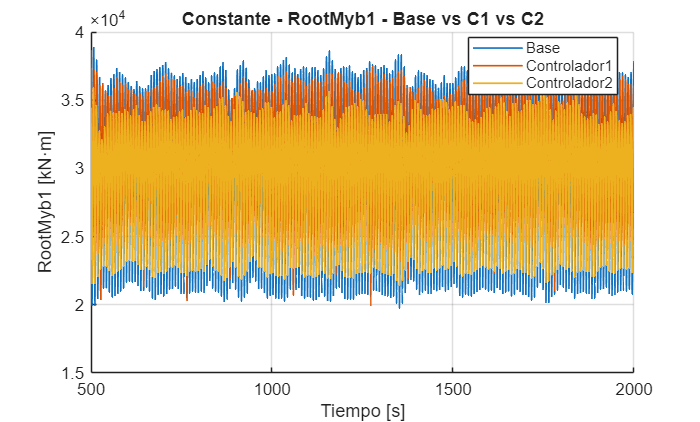

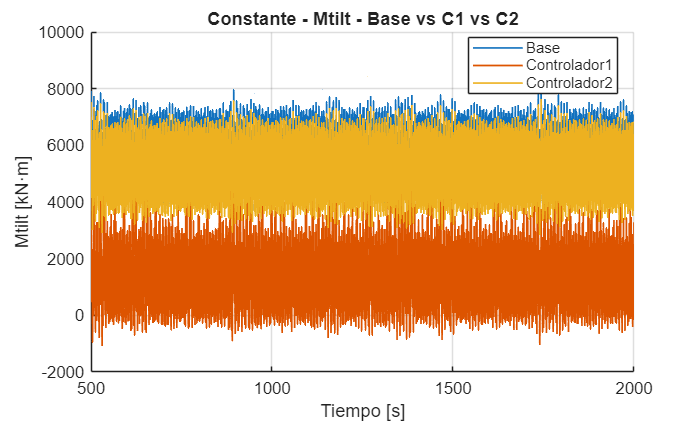

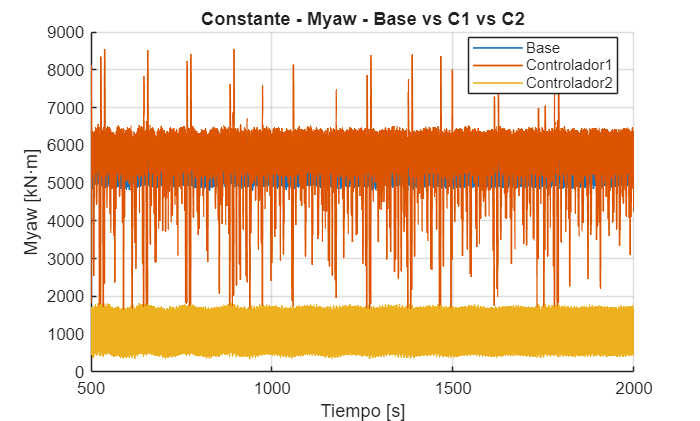

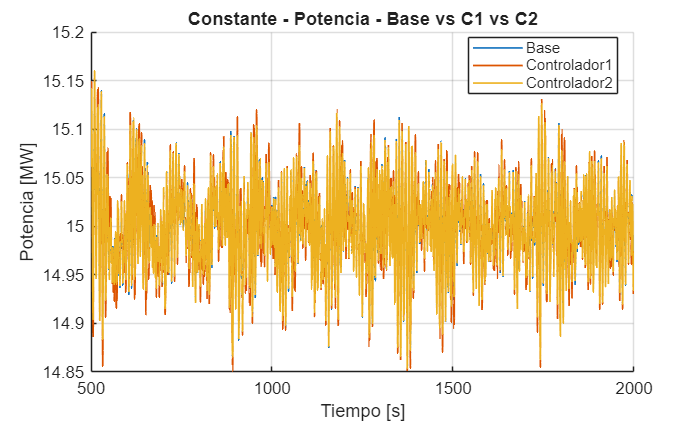

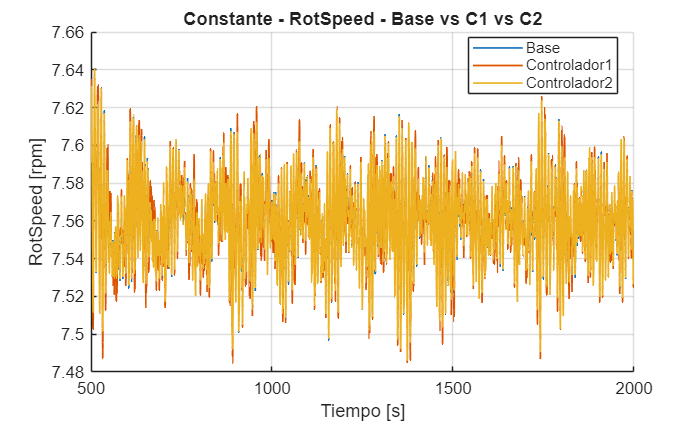

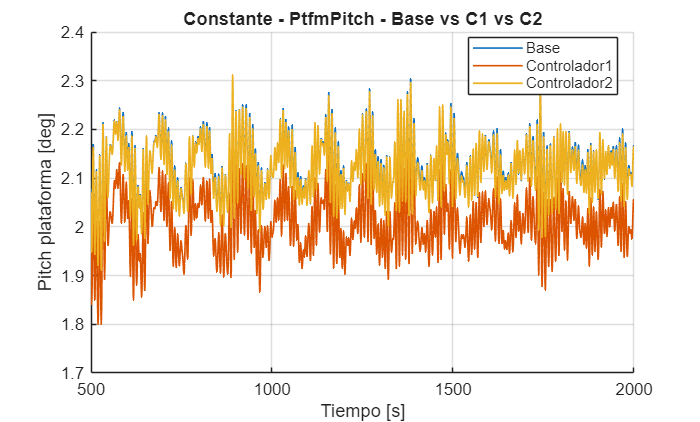

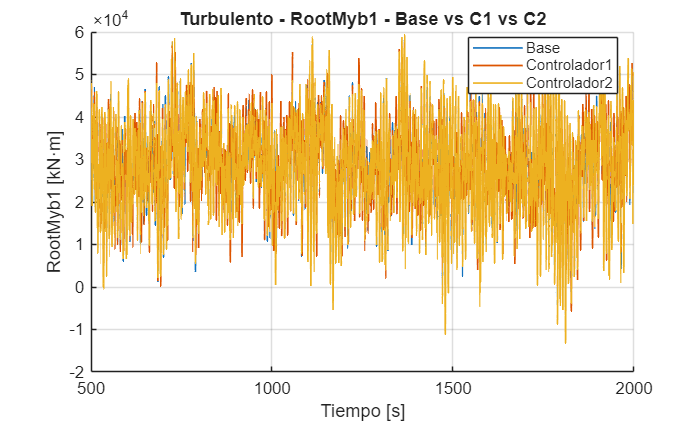

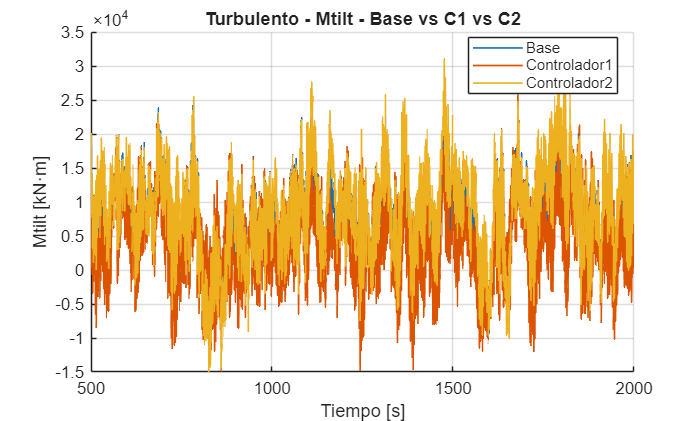


%% Figuras temporales RootMyb1, Mtilt, Myaw, potencia y rotor

tPlotStart = 500;

plotVars = [
    struct("var","RootMyb1", "ylab","RootMyb1 [kN·m]", "name","RootMyb1")
    struct("var","Mtilt", "ylab","Mtilt [kN·m]", "name","Mtilt")
    struct("var","Myaw", "ylab","Myaw [kN·m]", "name","Myaw")
    struct("var","GenPwr_MW", "ylab","Potencia [MW]", "name","Potencia")
    struct("var","RotSpeed", "ylab","RotSpeed [rpm]", "name","RotSpeed")
    struct("var","PtfmPitch", "ylab","Pitch plataforma [deg]", "name","PtfmPitch")
];

for g = grupos

    idxGroup = find(arrayfun(@(c) strcmp(string(c.grupo), g), cases));

    for p = 1:numel(plotVars)

        figure;
        hold on; grid on;

        for ii = idxGroup

            C = cases(ii);
            idxPlot = C.t >= tPlotStart;

            plot(C.t(idxPlot), C.S.(plotVars(p).var)(idxPlot), ...
                'LineWidth', 1, 'DisplayName', C.tipo);
        end

        xlabel('Tiempo [s]');
        ylabel(plotVars(p).ylab);
        title(g + " - " + plotVars(p).name + " - Base vs C1 vs C2");
        legend('Location','best');
        xlim([tPlotStart max(cases(idxGroup(1)).t)]);

        saveas(gcf, fullfile(figDir, sprintf('%s_%s_Base_C1_C2.png', ...
            char(g), plotVars(p).name)));
    end
end

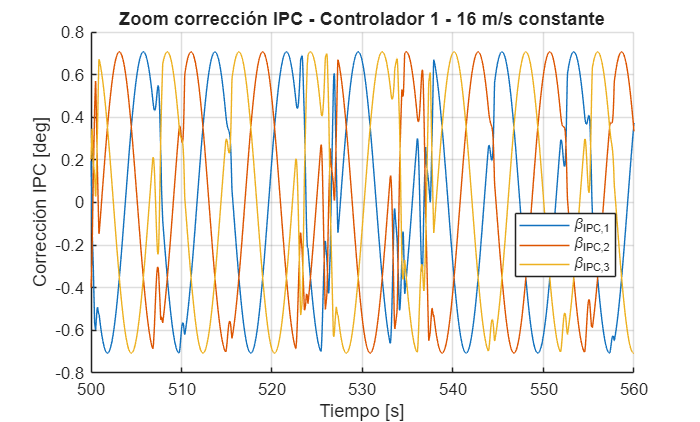

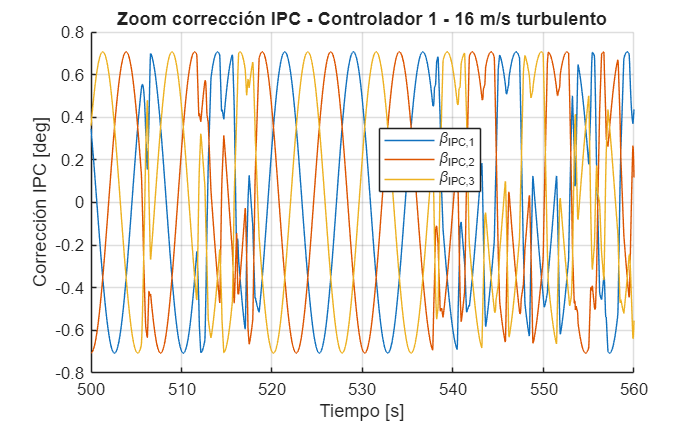

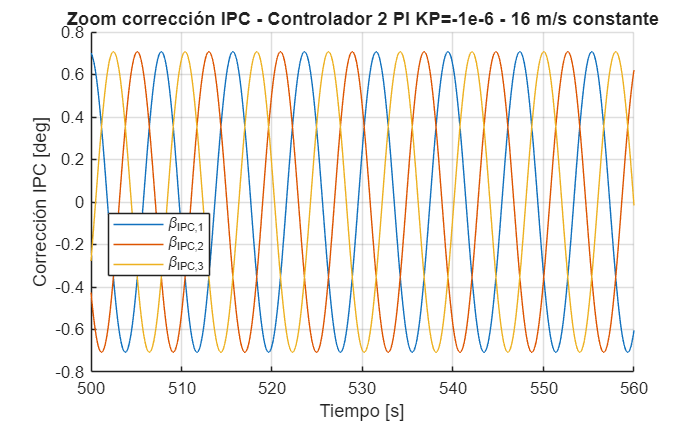

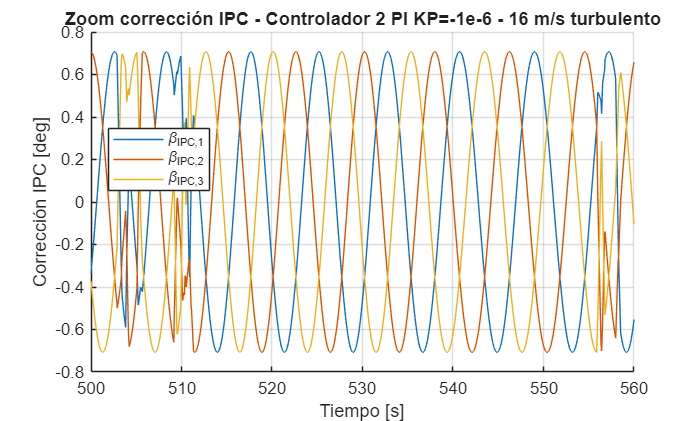


%% Zoom beta IPC para C1 y C2

tZoomIni = 500;
tZoomFin = 560;

for k = 1:numel(cases)

    C = cases(k);

    if strcmp(C.tipo, "Base")
        continue;
    end

    idxZoom = C.t >= tZoomIni & C.t <= tZoomFin;

    B = [C.S.BldPitch1(:), C.S.BldPitch2(:), C.S.BldPitch3(:)];
    betaMean = mean(B, 2, 'omitnan');

    betaIPC1 = B(:,1) - betaMean;
    betaIPC2 = B(:,2) - betaMean;
    betaIPC3 = B(:,3) - betaMean;

    figure;
    hold on; grid on;

    plot(C.t(idxZoom), betaIPC1(idxZoom), 'DisplayName','\beta_{IPC,1}');
    plot(C.t(idxZoom), betaIPC2(idxZoom), 'DisplayName','\beta_{IPC,2}');
    plot(C.t(idxZoom), betaIPC3(idxZoom), 'DisplayName','\beta_{IPC,3}');

    xlabel('Tiempo [s]');
    ylabel('Corrección IPC [deg]');
    title("Zoom corrección IPC - " + C.label);
    legend('Location','best');

    safeName = regexprep(char(C.id), '[^A-Za-z0-9_]+', '_');
    saveas(gcf, fullfile(figDir, sprintf('Zoom_betaIPC_%s.png', safeName)));
end


%% Guardar workspace

save(fullfile(outDir, 'comparativa_base_C1_C2.mat'), ...
    'cases', 'resumenComparativa', 'ipcDiagnostic', 'comparativaPct');


disp("Comparativa Base vs C1 vs C2 terminada.");

Comparativa Base vs C1 vs C2 terminada.


disp(outDir);

C:\Users\DAVID\Desktop\TFM_OpenFast\Resultados\Comparativa_Base_C1_C2



%% FUNCIONES AUXILIARES

function names = cleanNames(raw)

    if ischar(raw)
        names = string(cellstr(raw));
    elseif isstring(raw)
        names = raw(:);
    elseif iscell(raw)
        names = strings(numel(raw),1);

        for i = 1:numel(raw)
            item = raw{i};

            if iscell(item)
                item = item{1};
            end

            names(i) = string(item);
        end
    else
        error("Formato de nombres no reconocido.");
    end

    names = strtrim(names(:));
end

function y = getChan(C, name)

    idx = find(strcmpi(C.names, name), 1);

    if isempty(idx)
        warning("Canal no encontrado: %s", name);
        y = nan(size(C.X,1),1);
    else
        y = C.X(:,idx);
    end
end

function S = buildSignals(C)

    S.Wind1VelX = getChan(C, "Wind1VelX");

    S.GenPwr_MW = getChan(C, "GenPwr") / 1000;
    S.GenSpeed  = getChan(C, "GenSpeed");
    S.RotSpeed  = getChan(C, "RotSpeed");
    S.Azimuth   = getChan(C, "Azimuth");

    S.BldPitch1 = getChan(C, "BldPitch1");
    S.BldPitch2 = getChan(C, "BldPitch2");
    S.BldPitch3 = getChan(C, "BldPitch3");

    S.PtfmSurge = getChan(C, "PtfmSurge");
    S.PtfmSway  = getChan(C, "PtfmSway");
    S.PtfmHeave = getChan(C, "PtfmHeave");

    S.PtfmRoll  = getChan(C, "PtfmRoll");
    S.PtfmPitch = getChan(C, "PtfmPitch");
    S.PtfmYaw   = getChan(C, "PtfmYaw");

    S.RootMyb1 = getChan(C, "RootMyb1");
    S.RootMyb2 = getChan(C, "RootMyb2");
    S.RootMyb3 = getChan(C, "RootMyb3");

    psi = deg2rad(S.Azimuth);

    S.Mtilt = (2/3) .* ( ...
        S.RootMyb1 .* cos(psi) + ...
        S.RootMyb2 .* cos(psi + 2*pi/3) + ...
        S.RootMyb3 .* cos(psi + 4*pi/3));

    S.Myaw = (2/3) .* ( ...
        S.RootMyb1 .* sin(psi) + ...
        S.RootMyb2 .* sin(psi + 2*pi/3) + ...
        S.RootMyb3 .* sin(psi + 4*pi/3));
end

function DEL = calcDEL(x, m, Neq)

    x = x(:);
    x = x(~isnan(x));
    x = x - mean(x, 'omitnan');

    rf = rainflow(x);

    if istable(rf)
        ranges = rf.Range;
        counts = rf.Count;
    else
        c1 = rf(:,1);
        c2 = rf(:,2);

        if max(c1) <= 2 && max(c2) > max(c1)
            counts = c1;
            ranges = c2;
        else
            ranges = c1;
            counts = c2;
        end
    end

    DEL = (sum(counts .* ranges.^m) / Neq)^(1/m);
end

function NAT = calcNAT(t, beta, betaDotMax)

    t = t(:);
    beta = beta(:);

    valid = ~isnan(t) & ~isnan(beta);
    t = t(valid);
    beta = beta(valid);

    betaDot = zeros(size(beta));
    betaDot(2:end) = diff(beta) ./ diff(t);

    NAT = mean(abs(betaDot), 'omitnan') / betaDotMax;
end

function y = rmsDemean(x)

    x = x(:);
    x = x(~isnan(x));
    y = sqrt(mean((x - mean(x)).^2));
end    


Concluciones: la acción proporcional negativa mejora el comportamiento en viento constante y reduce el esfuerzo de pitch, pero no resulta robusta en viento turbulento, ya que incrementa el DEL medio en raíz de pala. Por tanto, no se selecciona como configuración final.